# **InverseJacobiDC**

[Inverse of the Jacobi elliptic function dc](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{dc}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(\sqrt{\frac{x^2 -1}{x^2 -m}}\left|m\right.\right) & m\le 1\\
\frac{{\textrm{cd}}^{-1} \left(x\left|m^{-1} \right.\right)}{\sqrt{m}} & m>1
\end{array}\right.$$



$${\mathrm{dc}}^{-1} \left(x,k\right)\equiv {\mathrm{dc}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parmeter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  Jacobi form of the elliptic integral of the first kind.

Domain:   If $-\infty <m\le 1$ then $\left|x\right|>1$ . If $m>1$ then $|x|<1$.For the specified domain, the  codomain  is the set of real numbers.

Basic features:

Special values:

   ${\mathrm{dc}}^{-1} \left(0\left|m\right.\right)=\textrm{NaN}$,    ${\mathrm{dc}}^{-1} \left(1\left|m\right.\right)=0$

${\mathrm{dc}}^{-1} \left(x\left|0\right.\right)=\sec^{-1} x$,    ${\mathrm{dc}}^{-1} \left(x\left|1\right.\right)=\infty$

Identities:


$${\mathrm{dc}}^{-1} \left(\mathrm{dc}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{dc}\left({\textrm{dc}}^{-1} \left(x\left|m\right.\right)\left|m\right.\right)=x$$


$K\left(m\right)$ is the complete elliptic integral of the first kind.

## Syntax

Y = InverseJacobiDC(X,K)

y = ijdc(x,k)

Y = mInverseJacobiDC(X,M)

y = mijdc(x,m)

## Dedcription

**Y = InverseJacobiDC(X,K)** return${\;\mathrm{dc}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the sdce size or any of them can be dcalar. **InverseJacobiDC** is the wrapper function which calls the functions **ijdc** element-wise via the function **ufun2**.

**y = ijdc(x,k)** return the value of ${\mathrm{dc}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real dcalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **ijdc** is the wrapper function which calls the functions **mijdc**.

**Y = mInverseJacobiDC(X,M)** returns ${\mathrm{dc}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (pardceter). X and M must be real and the sdce size or any of them can be dcalar. **mInverseJacobiDC** is the wrapper function which calls the functions **mijdc** element-wise via the function **ufun2**.

**y = mijdc(x,m)** compute value of $\mathrm{ds}\left(x\left|m\right.\right)$ for  argument x and the pardceter m. It is assumed that the input arguments are real dcalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijdc **call the function **melF **for calculation of ${\mathrm{dc}}^{-1} \left(x\left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 1.5;
[ijdc(x,k), InverseJacobiDC(x,k), mijdc(x,k^2), mInverseJacobiDC(x,k^2)]

ans =    0.940663976099643   0.940663976099643   0.940663976099643   0.940663976099643


% Maple 0.940663976099642_814


Accuracy.

fprintf('%.16g\n',mijdc(1.5,-4)) 

0.4159330998068017


%  Maple  0.4159330998068017_35

Special values

m=0.5;
disp(mijdc(0,m))  % m < 1 !!!

   NaN



x=1.5; % |x|>1
disp(mijdc(x,0) - asec(x)) 

     0



disp(mijdc(1,m))

     0



Identities

m = -2;
x = 0.5; % |x| <= 1
disp(mJacobiDC(mInverseJacobiDC(x,m),m)-x)

   NaN




k = 0.99995;
x = 0.9999*elK(k); % |x|<K
disp(InverseJacobiDC(JacobiDC(x,k),k)-x)

    -5.417888360170764e-13



m = 2; % m>1
x = 0.2; % |x|<1
disp(mijdc(x,m)-mijcd(x,1/m)/sqrt(m))

     0



m = 0.5;
x = 0.2;
disp(mijdc(-x,m)+mijdc(x,m))

   NaN



**Vector input**

m = [0.1, 0.5, 0.89, 0.99995];
x = 1.2*ones(size(m));
disp(mJacobiDC(mInverseJacobiDC(x,m),m)-x)

   1.0e-12 *

                   0  -0.000222044604925   0.000444089209850   0.135891298214119



**Matrix input**

m = [0.1, 0.5, 0.89; -1, -97, 0.99995 ]';
x = 1.2*ones(size(m));
disp(mJacobiDC(mInverseJacobiDC(x,m),m)-x)

   1.0e-12 *

                   0   0.000222044604925
  -0.000222044604925  -0.000222044604925
   0.000444089209850   0.135891298214119



## **Plot **

**Example 1**

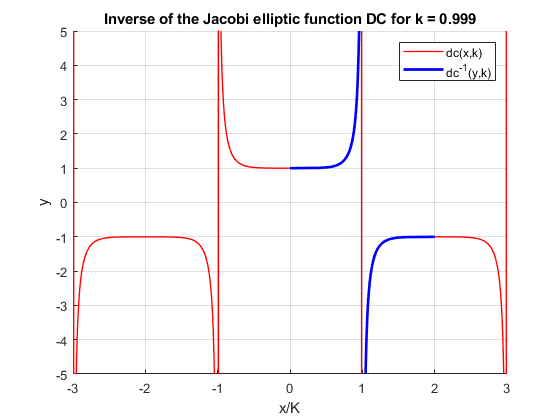

figure
hold on
x=-3:0.01:3;
k = 0.999;
M = elK(k);
plot(x,JacobiDC(M*x,k),'LineWidth',1.0,'Color','red')
x=-102:0.01:102;
plot(InverseJacobiDC(x,k)/M,x,'LineWidth',2,'Color','blue')
legend('dc(x,k)','dc^{-1}(y,k)') %,'Position','best')
xlabel('x/K')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function DC for k = %g',k))
grid on
hold off

**Example 2**

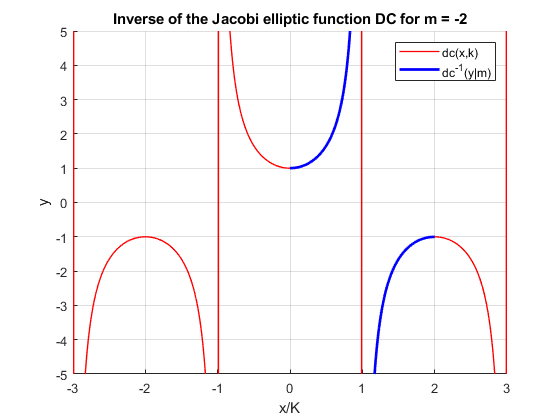

figure
hold on
x=-3:0.01:3;
m = -2;
if m < 1
    M = melK(m);
    xlabel('x/K')
elseif m > 1
    M = melK(1/m)/sqrt(m);
    xlabel('x/K')
else
    M = 1;
    xlabel('x')
end
plot(x,mJacobiDC(M*x,m),'LineWidth',1.0,'Color','red')
x=-102:0.01:102;
plot(mInverseJacobiDC(x,m)/M,x,'LineWidth',2,'Color','blue')
legend('dc(x,k)','dc^{-1}(y|m)') %,'Position','best')
ylabel('y')
%xlim([-1.1 1.1])
ylim([-5 5])
title(sprintf('Inverse of the Jacobi elliptic function DC for m = %g',m))
grid on
hold off

**Example 2**

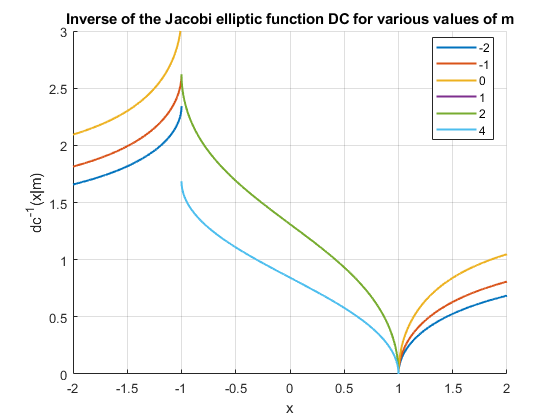

figure
hold on
X = -2:0.001:2;
M = [-2,-1,0,1,2,4];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiDC(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) 0 3])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function DC for various values of m')
%N=-400:0.01:1;
%X = ones(size(N));
%plot(X,mInverseJacobiDC(X,N),'k-.')
%plot(-X,-mInverseJacobiDC(X,N),'k-.')
xlabel('x')
ylabel('dc^{-1}(x|m)')

**Example 3**

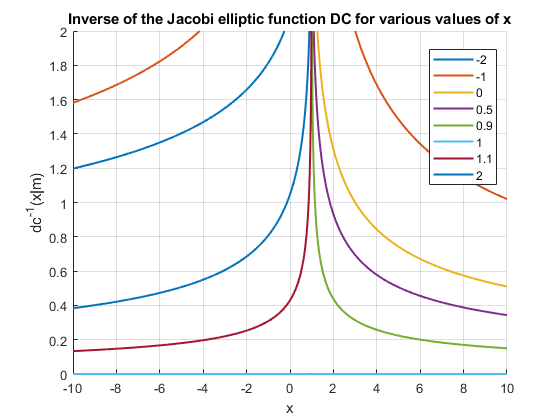

figure
hold on
M = -10:0.01:10;
X = [-2,-1,0,0.5,0.9,1,1.1,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiDC(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) 0 3])
ylim([0  2])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function DC for various values of x')
xlabel('x')
ylabel('dc^{-1}(x|m)')
%M = -200:0.01:1;
%F = mInverseJacobiDC(1,M);
%plot(M,F,'k-.')
%plot(M,-F,'k-.')
hold off

**Example 4**

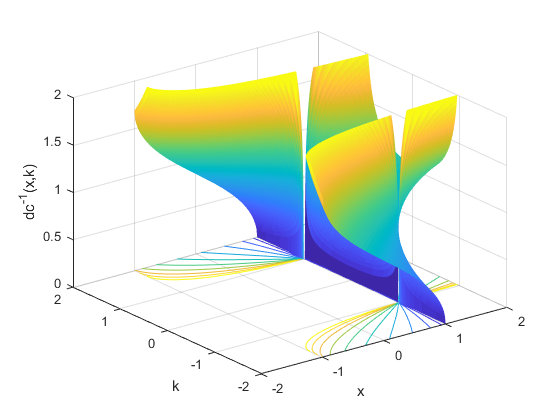

figure
x=-2:0.01:2;
k=-2:0.01:2;
zz = 2;
[X,M]=meshgrid(x,k);
hs=surfc(X,M,InverseJacobiDC(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view(3)
caxis([0 zz])
xlabel('x')
ylabel('k')
zlabel('dc^{-1}(x,k)')
zlim([0 zz])
grid on

**Example 4**

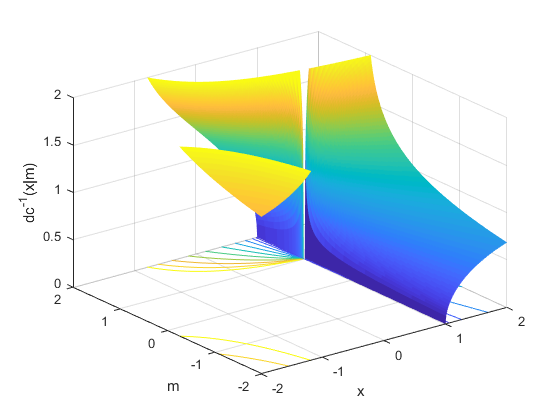

figure
x=-2:0.01:2;
m=-2:0.01:2;
zz = 2;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiDC(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view(3)
caxis([0 zz])
xlabel('x')
ylabel('m')
zlabel('dc^{-1}(x|m)')
zlim([0 zz])
grid on

**Example 5**

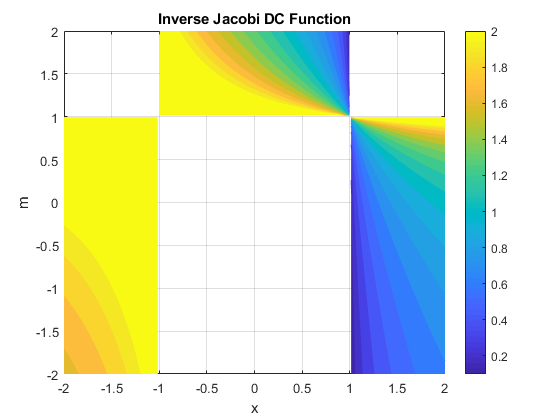

figure
f = @(x,m)mInverseJacobiDC(x,m);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi DC Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 6**

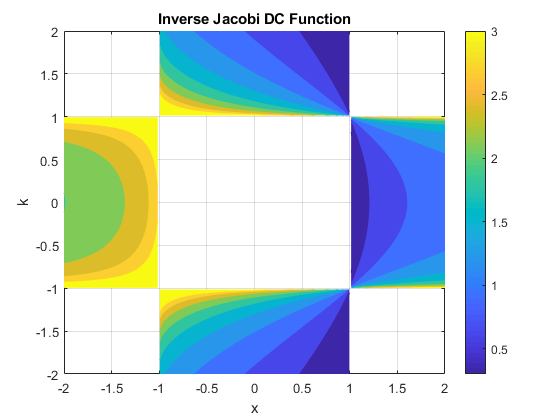

figure
f = @(x,k)InverseJacobiDC(x,k);
fcontour(f,[-2 2 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi DC Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

## See Also